Convolution:

syms t l
x = l^2

$$x = l^{2}$$

h = rectangularPulse(t-3,t,l)

$$h = \mathrm{rectangularPulse}\left(t-3,t,l\right)$$


y = int(x, l, t-3, t)

$$y = \frac{t^{3}}{3}-\frac{{\left(t-3\right)}^{3}}{3}$$

fplot(y)
hold on
g = 3*t^2-9*t+9

$$g = 3\,t^{2}-9\,t+9$$

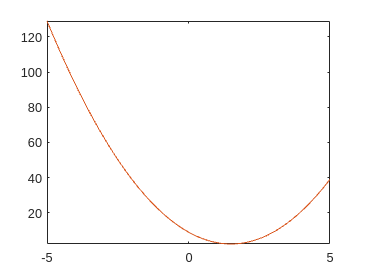

fplot(g)
hold off

Fourier Transform:

syms w
x = t^2*rectangularPulse(0, 3, t)

$$x = t^{2}\,\mathrm{rectangularPulse}\left(0,3,t\right)$$

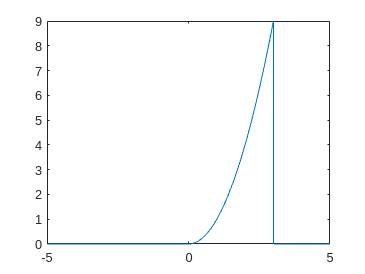

fplot(x) % original function
hold off


f = int(x*exp(j*w*t), t, 0, 3)

$$f = -\frac{2\,\mathrm{i}}{w^{3}}-\frac{{\mathrm{e}}^{3\,w\,\mathrm{i}}\,\left(9\,w^{2}+6\,w\,\mathrm{i}-2\right)\,\mathrm{i}}{w^{3}}$$

fplot(abs(f), [-10 10]) % calculated fourier
hold on

g = j*2/(w^3)+1/(w^3)*exp(-j*w*3)*(j*w^2*9+6*w-j*2)

$$g = \frac{2\,\mathrm{i}}{w^{3}}+\frac{{\mathrm{e}}^{-3\,w\,\mathrm{i}}\,\left(9\,w^{2}\,\mathrm{i}+6\,w-2\,\mathrm{i}\right)}{w^{3}}$$

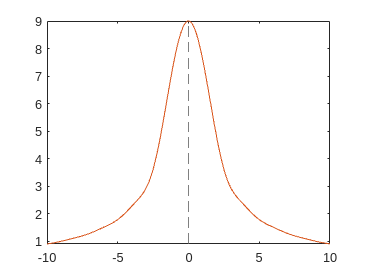

fplot(abs(g), [-10 10]) % guess function
hold off

Fourier Series:

syms t n
a0 = 1/pi

a0 = 0.3183

a1 = 1/2

a1 = 0.5000

an = 2/(pi*(1-4*n^2))

$$an = -\frac{2}{\pi \,\left(4\,n^{2}-1\right)}$$


appr = a0 + a1*sin(2*pi*t) + symsum(an*cos(4*pi*n*t),n,1,9)

$$appr = \frac{\sin\left(2\,\pi \,t\right)}{2}-\frac{2\,\cos\left(4\,\pi \,t\right)}{3\,\pi }-\frac{2\,\cos\left(8\,\pi \,t\right)}{15\,\pi }-\frac{2\,\cos\left(12\,\pi \,t\right)}{35\,\pi }-\frac{2\,\cos\left(16\,\pi \,t\right)}{63\,\pi }-\frac{2\,\cos\left(20\,\pi \,t\right)}{99\,\pi }-\frac{2\,\cos\left(24\,\pi \,t\right)}{143\,\pi }-\frac{2\,\cos\left(28\,\pi \,t\right)}{195\,\pi }-\frac{2\,\cos\left(32\,\pi \,t\right)}{255\,\pi }-\frac{2\,\cos\left(36\,\pi \,t\right)}{323\,\pi }+\frac{5734161139222659}{18014398509481984}$$

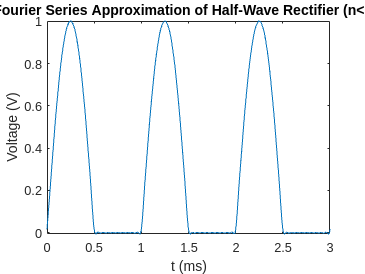

fplot(appr, [0 3])
xlabel('t (ms)')
ylabel('Voltage (V)')
title('Fourier Series Approximation of Half-Wave Rectifier (n<19)')
hold off

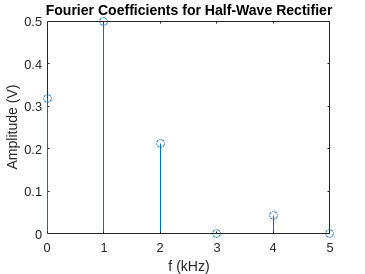


stem([0 1 2 3 4 5], [a0 a1 -subs(an, n, 1) 0 -subs(an, n, 2) 0])
xlabel('f (kHz)')
ylabel('Amplitude (V)')
title('Fourier Coefficients for Half-Wave Rectifier')